clear
close all


flag_mod = 0; % force to close the loop
flag_fft = 0;

FS_DAQ = 10000;
FS_CS = 8000;


% for noise test
time_init = 1;
time_test = 10; % used for extracting data
time_trigger = -0.5;
Range_time = [-1 10]; % used just for plotting
Range_current = [-10 10]; %uA


Range_voltage = [-11 11]; %kV
Range_charge = [-6 6]; %uC
Range_freq = [0 4000];
Range_PSD = [-120 0];





## capacitor test



% FName(1).name = 'raw_2e3_r_100kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1109_22_DAQ.dat';
% FName(1).text = '2000 Hz | HV: D754, red | GND: F784, blue';
% FName(1).time_init = 0.98;
% % % 
% FName(2).name = 'raw_1e3_r_100kV_002Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1125_12_DAQ.dat';
% FName(2).text = '1000 Hz | HV: D754, red | GND: F784, blue';
% FName(2).time_init = 0.98;
% % % 
% FName(3).name = 'raw_1e3_r_100kV_005Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1129_43_DAQ.dat';
% FName(3).text = '1000 Hz | HV: D754, red | GND: F784, blue';
% FName(3).time_init = 0.98;
% % % 
% FName(4).name = 'raw_5e2_r_100kV_005Hz_0500Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1134_41_DAQ.dat';
% FName(4).text = '500 Hz | HV: D754, red | GND: F784, blue';
% FName(4).time_init = 0.98;
% % 
% FName(5).name = 'raw_1e4_r_100kV_005Hz_10000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1137_07_DAQ.dat';
% FName(5).text = '10000 Hz | HV: D754, red | GND: F784, blue';
% FName(5).time_init = 0.98;
% 
% 
% Range_current = [-40 40]; %uA
% Range_charge = [-12 12]; %uC


## resistor test


FName(1).name = 'FR_L_1p0E6Ohm_l_100kV_0000Hz_0100Hz_10000Hz_2024_03_30_1723_39_DAQ.dat';
FName(1).text = '1MOhm';
% 
% FName(2).name = 'raw_5e3_r_100kV_002Hz_5000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_20_2128_07_DAQ.dat';
% FName(2).text = '5000Hz | HV: D754, red | GND: F784, blue';
% FName(2).time_init = 0.98;
% 
% FName(3).name = 'raw_2e3_r_100kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_20_2134_22_DAQ.dat';
% FName(3).text = '2000Hz | HV: D754, red | GND: F784, blue';
% FName(3).time_init = 0.98;
% % 
% FName(4).name = 'raw_2e3_r_100kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_20_2139_33_DAQ.dat';
% FName(4).text = '2000Hz device swapped | HV: F784, blue | GND: D754, red';
% FName(4).time_init = 0.98;
% % 
% FName(5).name = 'raw_2e3_r_80kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_20_2141_54_DAQ.dat';
% FName(5).text = '2000Hz device swapped up to 8kV | HV: F784, blue | GND: D754, red';
% FName(5).time_init = 0.98;
% 
% FName(6).name = 'raw_2e3_r_90kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_20_2150_49_DAQ.dat';
% FName(6).text = '2000Hz device swapped up to 9kV | HV: F784, blue | GND: D754, red';
% FName(6).time_init = 0.98;
% 
% FName(7).name = 'raw_2e3_r_100kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1018_54_DAQ.dat';
% FName(7).text = '1Mohm + 100nF | 2000Hz device after fully charged | HV: D754, red | GND: F784, blue';
% FName(7).time_init = 0.98;
% 
% FName(8).name = 'raw_2e3_r_100kV_002Hz_2000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_03_21_1102_52_DAQ.dat';
% FName(8).text = '10Mohm + 100nF | 2000Hz device after fully charged | HV: D754, red | GND: F784, blue';
% FName(8).time_init = 0.98;


Range_current = [-20 20]; %uA
Range_charge = [-1 2]; %uC



fName_DAQ = 'FR_L_1p0E6Ohm_l_100kV_0000Hz_0100Hz_10000Hz_2024_03_30_1723_39_DAQ.dat'

fName_Current = 'FR_L_1p0E6Ohm_l_100kV_0000Hz_0100Hz_10000Hz_2024_03_30_1723_39_current.dat'

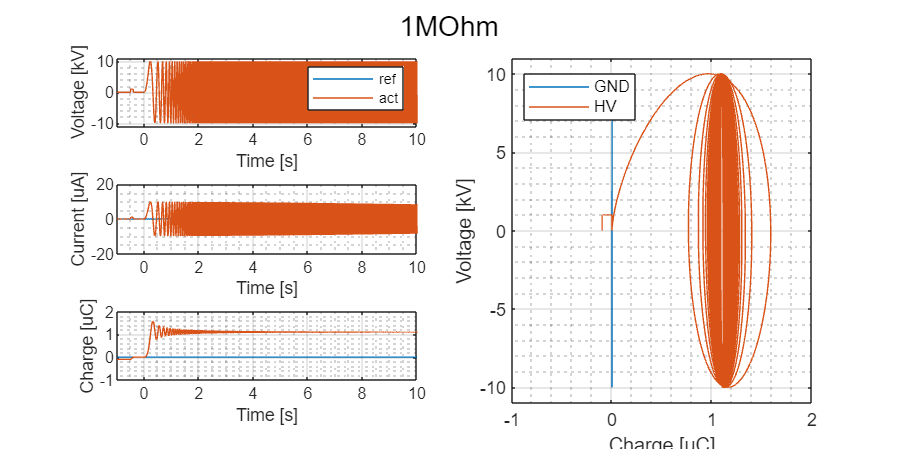


% XXX_s_33kV_010Hz_1000Hz_0010duty_02exp_000deg_000deg_000deg_000deg_2024_03_30_1445_47_DAQ.dat
% 12345678901234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890
% 0         1         2         3         4         5         6         7         8         9         0

for i = 1: length(FName)
    fName_DAQ = FName(i).name
    fName_Current = fName_DAQ;
    fName_Current(end-6: end + 4) = 'current.dat'



    tText = FName(i).text;
    flag_QI = fName_DAQ(7);
    % time_init_CS = FName(i).time_init_CS;

    [Time_DAQ, VoltageRef, ~, ~, ~, VoltageAct, Current_TREK, Current_Keithley, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~] = importfile_DAQ(fName_DAQ, 0);

    [Raw_GN, Raw_HV] = importfile_current(fName_Current);




    % FS_DAQ = str2num(fName_DAQ(5:7))

    Time_CS = (-time_init: 1/FS_CS: time_test - 1/FS_CS)';

    VoltageRef_CS = interp1(Time_DAQ, VoltageRef, Time_CS);
    VoltageAct_CS = interp1(Time_DAQ, VoltageAct, Time_CS);

    Current_GN = -toAmps(Raw_GN); % without round() -> rounding error problem of float numbers
    Current_HV = -toAmps(Raw_HV);
    Current_TREK = Current_TREK*1e-6;

    idx_trigger_HV = detectTrigger(Current_HV, 50e-9); % detectTrigger(Time, Data, time_trigger, threshould)
    Current_GN = shiftData(Time_CS, Current_GN, idx_trigger_HV, time_trigger, FS_CS);
    Current_HV = shiftData(Time_CS, Current_HV, idx_trigger_HV, time_trigger, FS_CS); 

    Current_GN = removeOffset(Time_CS, Current_GN, -0.9, -0.6); % removeOffset(Data, t0, t1, FS) remove DC offset using t0<t<t1 mean data value
    Current_HV = removeOffset(Time_CS, Current_HV, -0.9, -0.6); % removeOffset(Data, t0, t1, FS) remove DC offset using t0<t<t1 mean data value
    


    Current_GN = Current_GN - mean(Current_GN(0.1*FS_CS: 0.4*FS_CS));
    Current_HV = Current_HV - mean(Current_HV(0.1*FS_CS: 0.4*FS_CS));
    Current_TREK = Current_TREK - mean(Current_TREK(0.1*FS_DAQ: 0.4*FS_DAQ));
    % Current_Keithley = Current_Keithley - mean(Current_Keithley(1:0.8*FS_DAQ));
    % Current_GN(isnan(Current_GN)) = 0;
    % Current_HV(isnan(Current_HV)) = 0;

    Charge_GN = current2charge(Current_GN, FS_CS, time_init);
    Charge_HV = current2charge(Current_HV, FS_CS, time_init);
    Charge_TREK = current2charge(Current_TREK, FS_DAQ, time_init);

    if flag_QI == 'I'
        Charge_Keithley = current2charge(Current_Keithley, FS_DAQ, time_init_CS);
    elseif flag_QI == 'Q'
        Charge_Keithley = Charge_Keithley;
    end

    Current_GN_mod = Current_GN - (Charge_GN(end) - Charge_GN(time_init*FS_CS))/time_test;
    Current_HV_mod = Current_HV - (Charge_HV(end) - Charge_HV(time_init*FS_CS))/time_test;
    Current_TREK_mod = Current_TREK - (Charge_TREK(end) - Charge_TREK(time_init*FS_DAQ))/time_test;

    Charge_GN_mod = current2charge(Current_GN_mod, FS_CS, time_init);
    Charge_HV_mod = current2charge(Current_HV_mod, FS_CS, time_init);
    Charge_TREK_mod = current2charge(Current_TREK_mod, FS_DAQ, time_init);


    if flag_mod
        Current_GN = Current_GN_mod;
        Current_HV = Current_HV_mod;
        Current_TREK = Current_TREK_mod;
        Charge_GN = Charge_GN_mod;
        Charge_HV = Charge_HV_mod;
        Charge_TREK = Charge_TREK_mod;
    end
    f1 = figure(100 + i);

    ax1 = subplot(3, 2, 1);
    hold on
    plot(Time_DAQ, VoltageRef*1e-3, DisplayName='ref')
    plot(Time_DAQ, VoltageAct*1e-3, DisplayName='act')
    setPlot([], 'Time [s]', Range_time, 'Voltage [kV]', Range_voltage, 'NorthEast')

    ax2 = subplot(3, 2, 3);

    hold on
    plot(Time_CS, Current_GN*1e6, DisplayName='GN')
    plot(Time_CS, Current_HV*1e6, DisplayName='HV')
    % plot(Time_DAQ, Current_TREK*1e6, DisplayName='TREK')
    setPlot([], 'Time [s]', Range_time, 'Current [uA]', Range_current, 'none')

    ax3 = subplot(3, 2, 5);
    hold on
    plot(Time_CS, Charge_GN*1e6, DisplayName='GN')
    plot(Time_CS, Charge_HV*1e6, DisplayName='HV')
    % plot(Time_DAQ, Charge_TREK*1e6, DisplayName='TREK')

    setPlot([], 'Time [s]', Range_time, 'Charge [uC]', Range_charge, 'none')



    subplot(3, 2, [2 4 6])


    if flag_fft
        hold on
        plot_psd(Current_GN, FS_CS, 20e-6, 'GND');
        plot_psd(Current_HV, FS_CS, 20e-6, 'HV');
        setPlot([], 'Frequency [Hz]', Range_freq, 'PSD [dB]', Range_PSD, 'best')

    else
        hold on
        plot(Charge_GN*1e6, VoltageAct_CS*1e-3, DisplayName='GND')
        plot(Charge_HV*1e6, VoltageAct_CS*1e-3, DisplayName='HV')
        % plot(Charge_TREK*1e6, VoltageAct*1e-3, DisplayName='TREK')
        setPlot([], 'Charge [uC]', Range_charge, 'Voltage [kV]', Range_voltage, 'NorthWest')
    end



    linkaxes([ax1, ax2, ax3], 'x')
    sgtitle(tText)


end

function Current = toAmps(Raw)
Raw(Raw == 0) = nan;
Bias = 3/2;
conversionFactorADC = (3/(2^16-1));
conversionFactorIn = 1/(11*2e3);
Current = ((Raw*conversionFactorADC)-Bias)*conversionFactorIn;
end

function [Times, VoltageRef1kV, VoltageRef2kV, VoltageRef3kV, VoltageRef4kV, Voltage1kV, Current1uA, Voltage2kV, Current2uA, Voltage3kV, Current3uA, Voltage4kV, Current4uA, Angle1V, Angle2V, force1V, force2V, force3V] = importfile_DAQ(filename, k_keithley, dataLines)
%IMPORTFILE Import data from a text file
%  [TIMES, VOLTAGEREF1KV, VOLTAGEREF2KV, VOLTAGEREF3KV, VOLTAGEREF4KV,
%  VOLTAGE1KV, CURRENT1UA, VOLTAGE2KV, CURRENT2UA, VOLTAGE3KV,
%  CURRENT3UA, VOLTAGE4KV, CURRENT4UA, ANGLE1V, ANGLE2V, FORCE1V,
%  FORCE2V, FORCE3V] = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME for the default selection.  Returns the data as column
%  vectors.
%
%  [TIMES, VOLTAGEREF1KV, VOLTAGEREF2KV, VOLTAGEREF3KV, VOLTAGEREF4KV,
%  VOLTAGE1KV, CURRENT1UA, VOLTAGE2KV, CURRENT2UA, VOLTAGE3KV,
%  CURRENT3UA, VOLTAGE4KV, CURRENT4UA, ANGLE1V, ANGLE2V, FORCE1V,
%  FORCE2V, FORCE3V] = IMPORTFILE(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  [Times, VoltageRef1kV, VoltageRef2kV, VoltageRef3kV, VoltageRef4kV, Voltage1kV, Current1uA, Voltage2kV, Current2uA, Voltage3kV, Current3uA, Voltage4kV, Current4uA, Angle1V, Angle2V, force1V, force2V, force3V] = importfile("C:\Users\fukushima\Desktop\20231024_sensorTest\raw_HASEL_HVon_r_80kV_000Hz_1000Hz_0050duty_04exp_000deg_000deg_000deg_000deg_2023_10_24_1818_03_DAQ.dat", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 25-Oct-2023 07:32:16

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 3
    dataLines = [2, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "VoltageRef1kV", "VoltageRef2kV", "VoltageRef3kV", "VoltageRef4kV", "Voltage1kV", "Current1uA", "Voltage2kV", "Current2uA", "Voltage3kV", "Current3uA", "Voltage4kV", "Current4uA", "Angle1V", "Angle2V", "force1V", "force2V", "force3V"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
Times = tbl.Times;
VoltageRef1kV = tbl.VoltageRef1kV*1e3;
VoltageRef2kV = tbl.VoltageRef2kV;
VoltageRef3kV = tbl.VoltageRef3kV;
VoltageRef4kV = tbl.VoltageRef4kV;
Voltage1kV = tbl.Voltage1kV*1e3;
Current1uA = tbl.Current1uA;
Voltage2kV = -tbl.Voltage2kV*k_keithley/2; % Keithley current
Current2uA = tbl.Current2uA;
Voltage3kV = tbl.Voltage3kV;
Current3uA = tbl.Current3uA;
Voltage4kV = tbl.Voltage4kV;
Current4uA = tbl.Current4uA;
Angle1V = tbl.Angle1V;
Angle2V = tbl.Angle2V;
force1V = tbl.force1V;
force2V = tbl.force2V;
force3V = tbl.force3V;
end

function [Current_raw_GN, Current_raw_HV] = importfile_current(filename, dataLines)
%IMPORTFILE Import data from a text file
%  [MAC_34851806F784, MAC_34851805D754] = IMPORTFILE(FILENAME) reads
%  data from text file FILENAME for the default selection.  Returns the
%  data as column vectors.
%
%  [MAC_34851806F784, MAC_34851805D754] = IMPORTFILE(FILE, DATALINES)
%  reads data for the specified row interval(s) of text file FILENAME.
%  Specify DATALINES as a positive scalar integer or a N-by-2 array of
%  positive scalar integers for dis-contiguous row intervals.
%
%  Example:
%  [MAC_34851806F784, MAC_34851805D754] = importfile("\\space\fukushima\RM\prj_simpleEfficiency\experiment\20240125_ver2.1Test\raw_XXX_r_50kV_010Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2024_01_29_1341_31_current.dat", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 29-Jan-2024 13:42:05

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

% %% Set up the Import Options and import the data
% opts = delimitedTextImportOptions("NumVariables", 2);
%
% % Specify range and delimiter
% opts.DataLines = dataLines;
% opts.Delimiter = ",";
%
% % Specify column names and types
% opts.VariableNames = ["MAC_34851806F784", "MAC_34851805D754"];
% opts.VariableTypes = ["double", "double"];
%
% % Specify file level properties
% opts.ExtraColumnsRule = "ignore";
% opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(filename);

%% Convert to output type
Current_raw_GN = tbl.MAC_34851806F784;
Current_raw_HV = tbl.MAC_34851805D754;
end

function Charge = current2charge(Current, FS, time_init)
Charge = cumtrapz(Current)/FS;
Charge = Charge - Charge(round(time_init*FS));

end

function setPlot(label_title, label_x, Range_x, label_y, Range_y, position_legend)
fg = gcf();
fg.Position(3) = fg.Position(4)*2;
% fg.GraphicsSmoothing = 'off';

title(label_title)
xlabel(label_x)
ylabel(label_y)
xlim(Range_x)
ylim(Range_y)
if contains(position_legend, 'none', IgnoreCase=true)
    legend('off')
else
    legend('Location', position_legend)
end
grid on
grid minor
box on
end

function [rms_noise, snr] = plot_psd(data,FS, A, label)
rms_signal = A/sqrt(2); % assumption of full range sin signal: rms(Asin(wt)) = A/sqrt(2)
rms_noise = rms(data - mean(data));
snr = (rms_signal/rms_noise);

window = floor(length(data)/10);
% [pxx,f] = pwelch(data/A, gausswin(window), [], [], FS);
[pxx,f] = pwelch(data/A, [], [], [], FS);

psd = pow2db(pxx);
plot(f,psd, 'DisplayName', label);
xlim([0, FS/2]);

[pks,locs, peakwidth, peakProminence] =findpeaks(psd,f);
peaks_prominence = find(peakProminence>10);% &peakwidth>10);
text(gca,locs(peaks_prominence)-5,pks(peaks_prominence)+.2,[num2str(round(locs(peaks_prominence)))])

end


function idx = detectTrigger(Data, threshold)

Idx = find(Data > threshold);
idx = Idx(1) - 1;

% % for debug
% figure()
% hold on
% plot(Data)
% plot(idx, Data(idx), 'x')


end

function Out = shiftData(Time, Data, idx_trigger, time_trigger, FS)
idx_data_time0 = idx_trigger - round(time_trigger*FS);
% idx_data_time0 = idx_trigger;
[~, idx_time_time0] = min(abs(Time));
idx_diff = idx_time_time0 - idx_data_time0;


Out = zeros(size(Time));
Out(idx_diff + 1: idx_diff + length(Data)) = Data;
Out = Out(1: length(Time));

% % for debug
% figure()
% plot(Time, Out)



end

function Out = removeOffset(Time, Data, t0, t1)
[~, idx0] = min(abs(Time - t0));
[~, idx1] = min(abs(Time - t1));

Out = Data - mean(Data(idx0: idx1));


% % for debug
% figure()
% hold on
% plot(Time, Data)
% plot(Time(idx0: idx1), Data(idx0: idx1))
% grid on

end
